load EyesTestData.mat
load NotEyesTestData.mat
load CosineKNNModelKernel16.mat

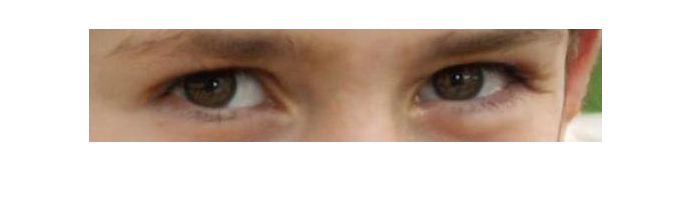

imagen = EyesTestData(:, :, :, 1);
imshow(imagen)

result = ejecutarPredictor(imagen, CosineKNNModelKernel16)

result = single
1

function[prediction] = ejecutarPredictor(imagen, clasificador) 

    imagenGris = rgb2gray(imagen);
    
    HOGFeatures = extractHOGFeatures(imagenGris, 'CellSize', [16 16]);
    HOGFeatures = [HOGFeatures 1];
    
    titulos = strings(width(HOGFeatures), 1);
    for i = 1: width(HOGFeatures)
        titulos(i) = "Atr " + int2str(i);
    end
    
    titulos(width(HOGFeatures)) = "Clase";
    
    tabla = array2table(HOGFeatures);
    tabla.Properties.VariableNames = titulos;
    
    prediction = single(clasificador.predictFcn(tabla));
end